# Notebook 02: Preprocessing and Feature Extraction

This research project contains 3 notebooks:

- Notebook 01: Project Overview

- Notebook 02: Preprocessing and Feature Extraction

- Notebook 03: ANN Training

You are currently running **Notebook 02**. Before running this notebook, you should have run Notebook 01 to get an understanding of the data you will be working with.

## Instructions

- Run each cell in order.

- Modify the lines that have green comments.

- This notebook, by default, assumes that time/samples are rows and channels are columns.

- Feel free to try more involved preprocessing steps, but assign your results back to the appropriate variables.

### Step 1: Ensure you are in the correct directory

cd(fileparts(matlab.desktop.editor.getActiveFilename))

## Procedure 1: Preprocessing

### Step 1: Load the dataset

clearvars
load("datasets\training_dataset.mat")

### Step 2: Visualize the raw data

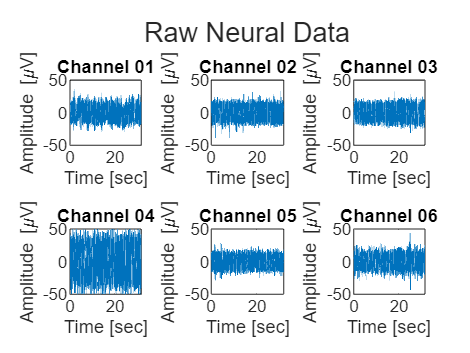

fig_1 = plot_raw_data(training_data);

%v = fft(transpose((training_data.raw_neural_data(:,1))))

%plot(v)






### Step 3: Filter the data

#### A. Provide information for designing the filter

Assuming you want to use a high-pass filter to denoise the neural signals, answer the following questions:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% What is the sampling frequency of your signals in units of Hz?
sample_rate = 30000; % Change this random value to the actual value of the sample rate
% What cutoff frequency (in Hz) would you use for a highpass filter?
cut_off_freq_L = 300; % Change this random value
cut_off_freq_H = 7500; % Change this random value
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

#### B. Design the filter and apply it to the signal

The function `butter` designs a filter using three arguments: filter order, normalized cut-off frequency, and filter type.

It returns the transfer function coefficients that match the provided specifications:


$$H(z) = \frac{B(z)}{A(z)} = \frac{b(1) + b(2)\,z^{-1} + b(n+1)\,z^{-n}}{a(1) + a(2)\,z^{-1} + a(n+1)\,z^{-n}}$$


t = linspace(0,30,948199)

t =          0    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0008    0.0009    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0014    0.0014    0.0014    0.0015    0.0015    0.0015    0.0016


filt_order = 4;
w = [cut_off_freq_L cut_off_freq_H];
norm_cut_off1 = w(2)/ (sample_rate/2)

norm_cut_off1 = 0.5000

norm_cut_off2 = w(1)/ (sample_rate/2)

norm_cut_off2 = 0.0200

[b, a] = butter(4,[150, 500]/ (sample_rate/2),'bandpass')

b = 1.0e-05 *

    0.1643         0   -0.6571         0    0.9856         0   -0.6571         0    0.1643


a =     1.0000   -7.7956   26.6022  -51.9022   63.3247  -49.4744   24.1717   -6.7521    0.8256



%[b2, a2] = butter(4,500/ (sample_rate/2),'low')
ch_init_conds = zeros(8, 6); %initial conditions for filter for all channels

[filt_neural_data, ~] = FilterX(b, a, training_data.raw_neural_data,ch_init_conds);
%[filt_neural_data, ~] = FilterX(b2, a2, filt_neural_data, zeros(4, 6) );
%[b3, a3] = butter(4,250/ (sample_rate/2),'low')
d = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',59,'HalfPowerFrequency2',61, ...
               'DesignMethod','butter','SampleRate',sample_rate);
d2 = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',119,'HalfPowerFrequency2',121, ...
               'DesignMethod','butter','SampleRate',sample_rate);
d3 = designfilt('bandstopiir','FilterOrder',2, ...
               'HalfPowerFrequency1',179,'HalfPowerFrequency2',181, ...
               'DesignMethod','butter','SampleRate',sample_rate);
filt_neural_data= filtfilt(d,filt_neural_data);
filt_neural_data= filtfilt(d2,filt_neural_data);
filt_neural_data= (filtfilt(d3,filt_neural_data));
%butter(filt_order, norm_cut_off, 'high'); % 4th order highpass filter

To apply the filter, we pass the transfer function to a precompiled method (`FilterX`) that has been optimized for speed. Alternatively, you can use MATLAB's [`filter()`](https://www.mathworks.com/help/matlab/ref/filter.html) function.

%ch_init_conds = zeros(4, 6); %initial conditions for filter for all channels
%[filt_neural_data] =  butter(filt_neural_data, 7500/(sample_rate/2), 'low');
%[filt_neural_data, ~] = FilterX(b, a, training_data.raw_neural_data, ch_init_conds);
%[filt_neural_data, ~] = %FilterX(b2, a2, filt_neural_data, zeros(3, 6));

%[filt_neural_data, ~] = (FilterX(b3, a3, filt_neural_data, zeros(4, 6)));



#### Step 4: Visualize the filtered data

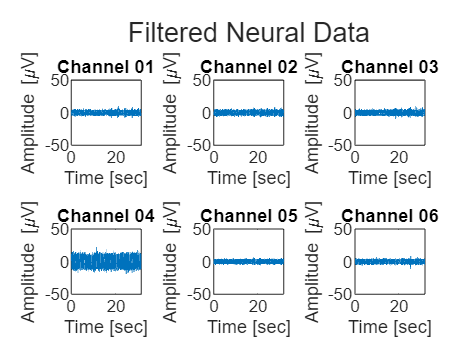

fig_2 = plot_filt_data(filt_neural_data, sample_rate);

## Procedure 2: Spike Detection

If your signal processing steps worked well, you should be able to detect some action action potentials.

### Step 1: Find the locations of the spikes (action potentials) for each channel

Your goal for this step is to provide the locations of spike occurrences in the `filt_neural_data` matrix.

You will start with the array `spike_locations`, which has the same shape as `filt_neural_data` and whose entries have been **initialized to zero**.

spike_locations = zeros(size(filt_neural_data))

spike_locations =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


spike_temp = zeros(size(filt_neural_data))

spike_temp =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Then, modify the code below to replace `0`s with `1`s whenever you find a spike. We do this to leverage MATLAB's [logical indexing](https://blogs.mathworks.com/loren/2013/02/20/logical-indexing-multiple-conditions/) functionality down the line.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
maxi = 28;
spike_temp(:,1)= (filt_neural_data(:,1))<-6;%-26.3;
spike_temp(:,2)= (filt_neural_data(:,2))<-6;%-23.2;
spike_temp(:,3)= (filt_neural_data(:,3))<-25;
spike_temp(:,4)= (filt_neural_data(:,4))<-36;
spike_temp(:,5)= (filt_neural_data(:,5))<-28.91;
spike_temp(:,6)= (filt_neural_data(:,6))<-40;
for i= 1:6;
    for j = 2:length(spike_locations(:,i));
        
        if spike_temp(j-1,i) == 0 && spike_temp(j,i) == 1;
            spike_temp(j-1,i) == 0 && spike_temp(j,i) == 1;
            
            spike_locations(j,i) = 1;
   
            
        end
    end
end
% This code generates random spike locations. Replace with a spike detection algorithm
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% spike_locations

### Step 2: Visualize the spike locations as spike trains in a raster plot

The raster plot below draws a vertical black line at each of the locations specified in `spike_locations`.

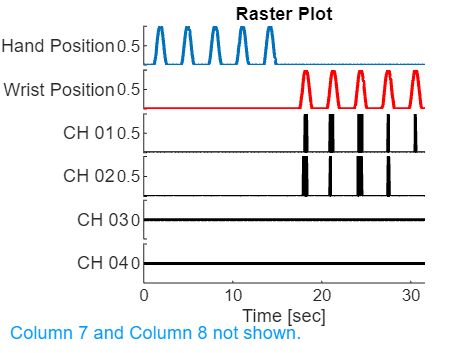

fig_3 = plot_spike_trains(spike_locations, training_data);

t1 = [1.15,2.5]

t1 =     1.1500    2.5000


t2 = [4.15,4.5]

t2 =     4.1500    4.5000


t3 = [7.5,8.5]

t3 =     7.5000    8.5000


t4 = [10.5,11.5 ]

t4 =    10.5000   11.5000


t5 = [13.5, 14.5]

t5 =    13.5000   14.5000


t6 = [17.7,18.8 ]

t6 =    17.7000   18.8000


t7 = [20.8, 21.8]

t7 =    20.8000   21.8000


t8 = [23.8, 24.8]

t8 =    23.8000   24.8000


t9 = [2,28.8]

t9 =     2.0000   28.8000


### Step 3: Plot the action potential waveforms using the spike locations

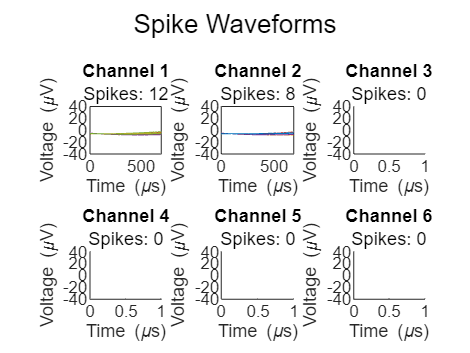

spike_waveforms = get_action_potentials(spike_locations, filt_neural_data, 'Spike Waveforms');

### Step 4: Calculate the SNR of each detected spike

First, let's explore how we have stored the waveforms associated with each spike. 

`spike_waveforms` is a [MATLAB cell array](https://www.mathworks.com/help/matlab/cell-arrays.html) that has one row per channel.

spike_waveforms

spike_waveforms = 6×1 cell array
    {1×12 cell  }
    {1×8  cell  }
    {0×0  double}
    {0×0  double}
    {0×0  double}
    {0×0  double}


Each of these rows is also a cell array containing a variable number of waveforms based on the information in `spike_locations`. 

spike_waveforms{:}

ans = 1×12 cell array
    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}


ans = 1×8 cell array
    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}    {22×1 single}



ans =

     []


ans =

     []


ans =

     []


ans =

     []



To access the waveforms, you need to specify the channel you want and the waveform you are interested in. 

chan_idx = 1; % random channel
waveform_idx = 4; % random waveform

The waveform itself is a vector containing `22` samples of neural data, which is equivalent to `0.1 ms` before and `0.6 ms `after the spike detection event.

waveform_data = spike_waveforms{chan_idx}{waveform_idx}

waveform_data = 22×1 single column vector
   -5.6529
   -5.7988
   -5.9386
   -6.0718
   -6.1978
   -6.3157
   -6.4247
   -6.5237
   -6.6117
   -6.6877


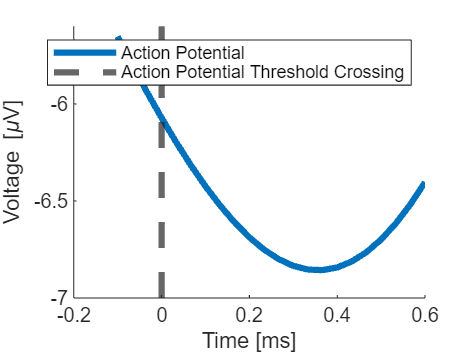

figure
waveform_time = (-3:1:18)'/training_data.sample_rate*1e3;
plot(waveform_time, waveform_data, LineWidth=3)
xline(0, LineWidth=3, LineStyle="--")
xlabel("Time [ms]")
ylabel("Voltage [\muV]")
legend(["Action Potential", "Action Potential Threshold Crossing"])
box off

Now, consider the image below, which shows action potentials as a function of distance to a neuron. Which action potential has the best SNR in the image below? Which channel of data provides the best SNR? Where might each channel be in relation to a given neuron? Are any channels recording from multiple neurons? 

One of your requirements for this research project is to determine if there are any statistical differences in the SNR among the electrodes.

For more context about the image below, read the document titled *"Introduction to Neural Recordings"* under the Neural Recordings Reading Assignment on Canvas. 

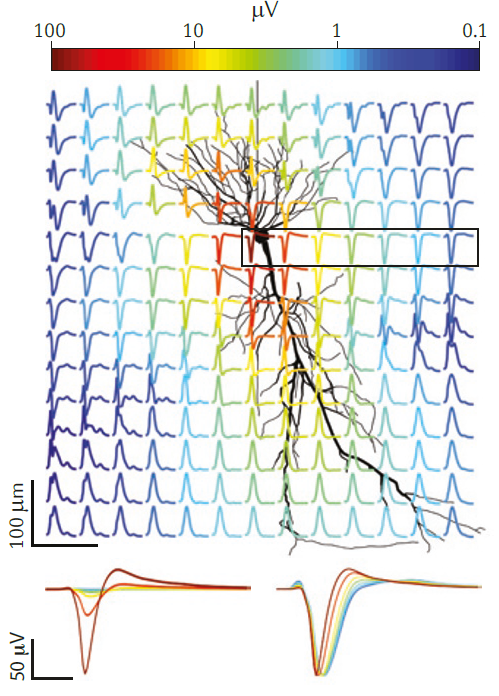

Calculate the SNR of each waveform in `spike_waveforms`. Use the following code to access each waveform:

for chan_idx = 1:6 % for each channel
    chan_waveforms = spike_waveforms{chan_idx};
    for waveform_idx = 1:length(chan_waveforms) % for each waveform in the channel
        waveform_data = chan_waveforms{waveform_idx};
        %%%%%%%%%%%%%%%%%%%%%%%% YOUR SNR CODE GOES HERE %%%%%%%%%%%%%%%%%%%

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end
end

After you've calculated SNRs you should have 6 distributions total (1 for each channel). Make sure to **plot the SNR values** and **run stats**! 

## Procedure 3: Feature Extraction

### Step 1: Implement your feature extraction algorithm

The only requirement for generating features is that the length of your `neural_features` must match the size of the kinematics. The reason for this is that the kinematics are acting as labels for your features. For more information about this requirement, check notebook 03 on training the neural network.

If the lengths don't match as a result of your calculations, you can [pad the array with zeros](https://www.mathworks.com/help/images/ref/padarray.html).


%%%%%%%%%%%%%%%%%%%%%%%%% CHANGE THIS CODE %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%neural_features = %filt_neural_data(:,1)



%%
% nonsensical code that passes the assertion below
length(training_data.hand_kinematics)

ans = 948199

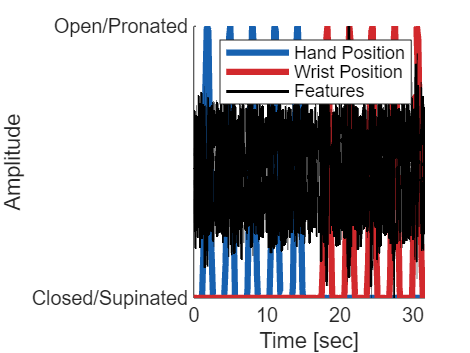

%neural_features = spike_locations(1,:)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
assert(length(neural_features) == length(training_data.hand_kinematics), "EXPECTED EQUAL LENGTH!")
neural_features = normalize(neural_features, "range", [0 1]);
plot_features(training_data, neural_features);

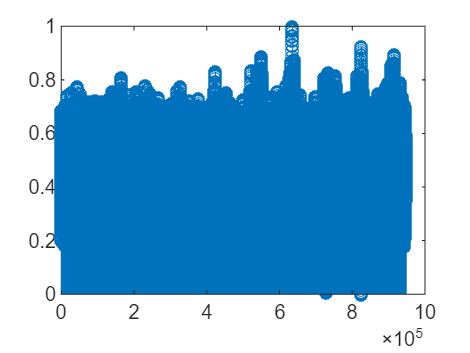

figure;
stem(neural_features)

save("results\features", "neural_features")

## Helper Functions

This section contains the functions used for data visualization throughout this notebook. You do not need to change or understand the code below, but you are welcome to do so if it helps with your project.

function fig_handle = plot_raw_data(training_data)
[num_samples, num_chans] = size(training_data.raw_neural_data);
timestamps = (1:num_samples)/training_data.sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, training_data.raw_neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Raw Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_filt_data(neural_data, sample_rate)
[num_samples, num_chans] = size(neural_data);
timestamps = (1:num_samples)/sample_rate;

fig_handle = figure;
fig_raw = tiledlayout("flow");
for i = 1:num_chans
    ax_handles{i} = nexttile;
    plot(timestamps, neural_data(:,i))
    title(sprintf('Channel %02d', i))
    xlabel('Time [sec]')
    ylabel('Amplitude [\muV]')
end
title(fig_raw, 'Filtered Neural Data')
linkaxes([ax_handles{:}], 'xy');
ylim([-50, 50])
end


function fig_handle = plot_spike_trains(spike_locations, training_data)
fig_handle = figure;
t = (0:1:length(spike_locations)-1)'/training_data.sample_rate;
raster_handle = stackedplot(t, [training_data.hand_kinematics, spike_locations], LineWidth=1.5);
raster_handle.Color = "black";
raster_handle.LineProperties(1).Color = "#0072BD";
raster_handle.LineProperties(2).Color = "red";
raster_handle.DisplayLabels = ["Hand Position", "Wrist Position", "CH 01", "CH 02", "CH 03", "CH 04", "CH 05", "CH 06"];
raster_handle.XLabel = "Time [sec]";
raster_handle.Title = "Raster Plot";
end


function spike_waveform_container = get_action_potentials(spike_trains, neural_data, plot_title)
[~, n_chans] = size(neural_data);
figure()
sgtitle(plot_title)
spike_waveform_container = cell(n_chans,1);
for chan=1:n_chans
    neg_offset = -3;
    pos_offset = 18;
    spike_locations = spike_trains(:,chan);
    spike_locations = find(spike_locations == 1);
    spike_count = sum(spike_trains);
    spikes = cell(1, spike_count(chan));

    subplot(2, 3, chan)
    for spike_idx = 1:length(spikes)
        idx_start = spike_locations(spike_idx) + neg_offset;
        idx_end = spike_locations(spike_idx) + pos_offset;
        try
            spikes{spike_idx} = neural_data(idx_start:idx_end, chan);
            plot(0:33:700, spikes{spike_idx});
        catch
        end
        hold on;
        spike_waveform_container{chan} = spikes;
    end
    xlabel('Time (\mus)')
    ylabel('Voltage (\muV)')
    hold off
    title(['Channel ' num2str(chan)])
    subtitle(['Spikes: ' num2str(length(spikes))])
    ylim([-40, 40])
end
end

function fig_handle = plot_features(training_data, neural_features)
fig_handle = figure;
hold on
t = (0:1:length(training_data.hand_kinematics)-1)/training_data.sample_rate;
plot(t, training_data.hand_kinematics(:,1), 'LineStyle','-','Color', "#1761B0", 'LineWidth', 3)
plot(t, training_data.hand_kinematics(:,2), 'LineStyle','-','Color', "#D2292D", 'LineWidth', 3)
plot(t, neural_features,'Color',"#000000" ,'LineWidth', 1.5)
hold off
box off
ylim([0 1])
yticks([0 1])
yticklabels({"Closed/Supinated", "Open/Pronated"})
xlabel("Time [sec]")
ylabel("Amplitude")
legend(["Hand Position", "Wrist Position", "Features"])
end